####                                                                        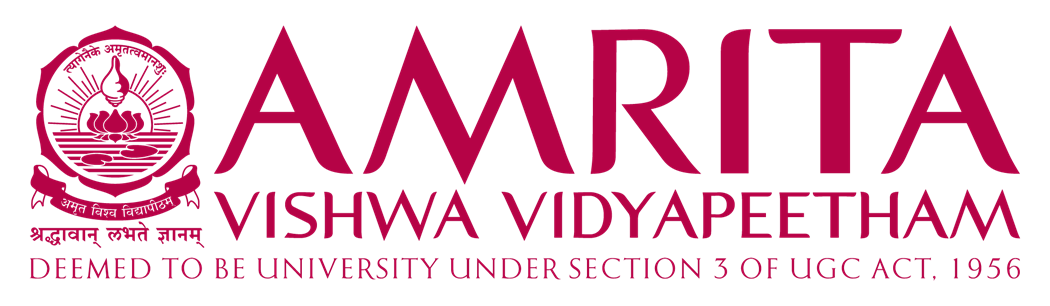

#                                                      22MAT220  -   Mathematics for Computing 3

**Team Members,**

**Raghuram Sekar          - CB.SC.U4AIE24247**

**Meghana Kotharu        - CB.SC.U4AIE24232**

**Jithin Reddy                 - CB.SC.U4AIE24230**

**Praveen Reddy            - CB.SC.U4AIE24243**

#                                                             LLM PRUNING USING ADMM

# INTRODUCTION

#### GOAL: Prune LLMs efficiently, while "preserving model performance" - fine tuning is the challenge here

pruning: remove unimportant weights - reduce size - speed up performance

But, the challenge is we dont know how much weights to remove, such that the performance of the model doesnt change much

Methods used:

- ADMM - for efficient weight update

- Wanda inspired mask selection - using activation aware pruning

- Iterative pruning +update - improves pruning gradually

#### TO DO: Prune each LAYER of a transformer model individually and update the weights optimally, based on a GIVEN sparsity mask

OBJECTIVE FUNCTION : $\underset{\hat{w} }{\min \;} \;{\left\|X_l \;W_l -X_l \left(M_l \bigodot \hat{W_l } \right)\right\|}_2^2$    ------ Reconstruction Loss

$X_l$* - Input activations (Callibration inputs) into the *$l^{\textrm{th}}$* layer                                                     batch size(b) *m *

$W_l$* - weight matrix of the *$n^{\textrm{th}}$* layer                                                                                           m*n*

$M_l$* - Sparsity pruning mask for the *$i^{\textrm{th}}$* layer (1=keep; 0=prune)                                              *${\left\lbrace 0,1\right\rbrace }^{m*n}$

$\hat{W_l }$ - *updated weight matrix for the *$l^{\textrm{th}}$* layer after pruning and ADMM optimization                 m*n*

# EXISTING APPROACHES

#### 1. USING n LINEAR REGRESSIONS

    Disadvantages of Linear regression

        1) need to do one regression per o/p neuron (column in W)

        2) each has a different pruning pattern  - different mask- different subset of X

        3) Thus, requires n seperate matrix inversions - O($\left.m^3 n\right)$

#### 2. USING GRADIENT DESCENT

        - Replaces the closed form matrix inversion(n linear reg.) with iterative optimization, using gradient descent

$L\left(\hat{W} \right)={\left\|X\;W-X\;\left(M\bigodot \hat{W} \right)\right\|}_F^2$            ------ loss function

F: Frobenius norm: L2 norm of vector of all elements in matrix  

let   X $\in$ $R^{b*n}$

       $\hat{W}$ $\in$ $R^{m*n}$          ------ *updated weight matrix after pruning*

       M $\in$ ${\left\lbrace 0,1\right\rbrace }^{m*n}$     ------ pruning masks

       $\tilde{W}$ = $M\bigodot \hat{W}$       ------ masked weights

        Y = X W                              --------- original output

        $\hat{Y}$= X$\tilde{W}$   = X($M\bigodot \hat{W}$)  

Now, the loss function becomes:


$$L={\left\|Y-\hat{Y} \right\|}_F^2$$
 
$$={\left\|Y-X\tilde{W} \right\|}_F^2$$


$\frac{\partial L}{\partial \tilde{W} }$ =  -2$X^T$(Y-$X\tilde{W}$)   ; $\frac{\partial \tilde{W} }{\partial \hat{W} }$   =   $\frac{\partial \left(M\bigodot \hat{W} \right)}{\partial \hat{W} }$  =  $M$

so, $\nabla_{\hat{W} } L=-2X^T \left(Y-X\left(M\bigodot \hat{W} \right)\right)\bigodot M$               ---------- because,     $\frac{\partial L}{\partial \hat{W} }$ = $\frac{\partial L}{\partial \tilde{W} }\;\ldotp \;\frac{\partial \tilde{W} }{\partial \hat{W} }\;$  

thus, rewriting, the update equation is proportional to $2X^T X\left(\left(M\bigodot \hat{W} \right)-W\right)\bigodot M$

disadvantages of Gradient Descent

1) Slower convergence, sensitive to learning rate

2) may need 100s of steps per layer

3) No guarantee of optimality

4) each update is faster O($\left.m^2 n\right)$, but too many updates are needed

#### 3. ADMM - alternatiing direction method of multipliers (convex optimization)

- same iteration complexity as gradient descent but converges much faster

Instead of keeping the mask inside the loss, the problem can be rewritten as:

     $\underset{\hat{w} }{\min \;} \;{\left\|XW-X\hat{W} \right\|}_2^2$        s.t. $\hat{W} \bigodot \left(1-M\right)=0$

- The objective ensures the pruned model matches the original outputs.

- The constraint enforces that invalid weights (where M=0) remain zero. (Hard pruning)

**APPLICATION OF ADMM**

To apply ADMM, the constraint is expressed via an indicator function:


$$g\left(Z\right)\left\lbrace \begin{array}{ll}
0 & \textrm{if}\;Z\bigodot \left(1-M\right)=0\\
\infty  & \textrm{otherwise}
\end{array}\right.$$


and an auxiliary variable $Z$ is introduced, leading to:

$\underset{\hat{w} ,Z}{\min \;} \;f\left(\hat{w} \right)+g\left(Z\right)$  s.t. $\hat{W} =Z$

where


$$f\left(\hat{W} \right)=\;$$

$${\left\|XW-X\hat{W} \right\|}_2^2$$


## ADMM Iterations

The augmented Lagrangian gives rise to three alternating update steps:

        1. $\hat{W}$**- update (data-fitting step): **Solves a ridge regression-like subproblem

                
$$\begin{array}{l}
{\hat{W} }^{k+1} =\arg \;\underset{\hat{W} }{\min \;} ||\textrm{XW}-X\hat{W} ||^2 +\frac{\rho }{2}\;||\;\hat{W} -Z^k +U^k ||^2 \\
{\Rightarrow \;\hat{W} }^{k+1} ={\left(X^T X+\rho I\right)}^{-1} \;\;\left(X^T \textrm{XW}+\rho \left(Z^k -U^k \right)\right)
\end{array}$$


**         2. **$Z$**- update (mask projection step): **Projects the weights onto the valid set defined by the mask:

                 
$$Z^{k+1} =\left({\hat{W} }^{k+1} +U^k \right)\bigodot M$$


**         3. Dual variable update:**Adjusts the Lagrange multiplier to enforce consistency:

                 
$$U^{k+1} =U^k +{\hat{W} }^{k+1} -Z^{k+1}$$


Here, $\rho$ is a penalty parameter controlling the trade-off between the two objectives.

## Advantages of ADMM

- **Efficiency:** The expensive matrix inverse ${\left(X^T X+\rho I\right)}^{-1}$ can be precomputed once, reducing per-iteration complexity to O($\left.m^2 n\right)$, comparable to gradient descent.

- **Faster Convergence:** ADMM converges in far fewer iterations than plain gradient descent.

- **Constraint Satisfaction:** The Z-update explicitly enforces the pruning mask(hard pruning using projection), ensuring invalid weights are zero at every iteration.

- **Interpretability:** The updates resemble ridge regression for valid weights while aggressively pulling pruned weights toward zero.

- ADMM alternates between two perspectives:

- **Fit the data:** Adjust valid weights to approximate the original outputs.

- **Respect the mask:** Project the adjusted weights back into the pruned weight space.

- The dual variable U ensures that these two views gradually agree, leading to a feasible and accurate pruned model.

### Mask Selection and Preconditioning

In the previous section, the pruning mask was assumed to be given. However, the performance of pruning strongly depends on how the mask is chosen. A poor mask can discard critical weights and lead to significant accuracy degradation. To address this, the authors adopt a pruning rule inspired by **Wanda (Sun et al., 2023)**.

The key idea of Wanda is that pruning should not be based on weight magnitude alone, but on the interaction between weights and the scale of their input activations. Specifically, the score used to rank weights is:

Scoreij=$|W_{\textrm{ij}} \;|\ldotp {||X_j ||}_2 \;$

where $|W_{\textrm{ij}} \;|$ is the weight connecting input neuron j to output neuron i, and ${||X_j ||}_2 \;$is the norm of the j-th input feature. 

The authors reformulate this idea through **preconditioning**. The procedure is:

- Multiply the weight matrix by the feature norms ($W^{\prime } =W\ldotp D$).

- Divide the input matrix by the same norms ($X^{\prime } =X\;D^{-1}$).

- Run the ADMM update on the transformed system.

- Normalize the weight matrix back.

This transformation ensures that the forward pass Y=XW remains unchanged, while simultaneously making simple **magnitude pruning on W′** equivalent to Wanda’s importance criterion. Thus, the authors effectively embed Wanda’s pruning rule into their ADMM framework without additional complexity.

Notably, unlike the original Wanda paper which enforces a fixed number of weights per output neuron, the authors found that this constraint slightly reduces performance when combined with weight updates. Therefore, they prune based on global layer-wide scores instead of per-output scores.

### Iterative Pruning

One-shot pruning, where a mask is applied once to reach the target sparsity, often causes large accuracy drops, especially for aggressive sparsity levels. To mitigate this, the authors propose **iterative pruning**, where sparsity is increased gradually over multiple steps, with ADMM weight updates applied at each step.

They adopt the **cubic sparsity schedule** from Zhu & Gupta (2018):


$$s_t =s_f {\left(\frac{t}{k_s }\right)}^3$$


where $s_f$ is the target final sparsity, 

          $k_s$ is the total number of pruning steps

          $s_t$ is the sparsity at step t. 

This schedule prunes weights more conservatively at the beginning and more aggressively towards the end, giving the model time to adapt.

At each pruning step:

- Weights are scored using the Wanda-inspired preconditioning rule.

- Weights with the lowest scores are set to zero, until the layer reaches sparsity $s_t$

- ADMM updates are run to rebalance the surviving weights, reducing the output reconstruction error.

A further refinement is that instead of pruning directly based on the projected weights $Z^k$, the authors prune according to $W^{k+1} +U^k$, which is theoretically optimal under the ADMM formulation when the sparsity constraint is not fixed but progressively increasing.

**structured sparsity**, particularly 2:4 sparsity, which is widely supported in modern GPUs. Here, in every block of four weights, the two largest are always preserved, and pruning is applied only to the remaining two, ensuring compatibility with hardware acceleration.

In summary, iterative pruning makes the transition to high sparsity levels smoother, while ADMM ensures that the model maintains accuracy at each stage by optimally adapting the surviving weights.

%% Layerwise Iterative Pruning with ADMM - Multi-layer Toy Network
clc; clear; close all;

%% Parameters
input_size = 5;
hidden_size = 4;
output_size = 2;
num_samples = 30;

k = 30;        % total ADMM iterations
ks = 10;       % sparsification iterations
sf = 0.5;      % final sparsity fraction
lambda = 0.1;  % dampening factor
rho = 1;       % ADMM penalty factor

learning_rate = 0.01;

%% Generate toy data
X = randn(num_samples, input_size);
Y = randn(num_samples, output_size);

%% Initialize weights
W1 = randn(input_size, hidden_size);
W2 = randn(hidden_size, output_size);

% ADMM variables
Z1 = zeros(size(W1)); U1 = zeros(size(W1));
Z2 = zeros(size(W2)); U2 = zeros(size(W2));

%% Preprocessing normalization
epsilon = 1e-6;
norm_X = norm(X, 'fro')^2 + epsilon;
W1 = W1 * norm_X; W2 = W2 * norm_X;
X = X / norm_X;

%% Activation function
sigmoid = @(x) 1./(1+exp(-x));

%% Compute XX matrices
XX1 = X'*X + lambda*eye(input_size);
XX2 = (sigmoid(X*W1))' * sigmoid(X*W1) + lambda*eye(hidden_size);


XXW1 = XX1*W1;
XXW2 = XX2*W2;

XX1_inv = inv(XX1 + rho*eye(input_size));
XX2_inv = inv(XX2 + rho*eye(hidden_size));


%% ADMM Iterations (layerwise)
loss_log = zeros(1,k);

for step = 1:k
    % Compute activations for layer 1
    H = sigmoid(X*W1);
    
    %% Layer 1 pruning
    if step <= ks
        si1 = sf*(step/ks)^3;
        absWU1 = abs(W1 + U1);
        num_keep1 = ceil((1-si1)*numel(W1));
        thresh1 = sort(absWU1(:), 'descend');
        thresh_val1 = thresh1(num_keep1);
        M1 = absWU1 >= thresh_val1;
    end
    Z1 = (W1 + U1) .* M1;
    U1 = U1 + (W1 - Z1);
    W1 = XX1_inv * (XXW1 + rho*(Z1 - U1));
    
    %% Layer 2 pruning
    if step <= ks
        si2 = sf*(step/ks)^3;
        absWU2 = abs(W2 + U2);
        num_keep2 = ceil((1-si2)*numel(W2));
        thresh2 = sort(absWU2(:), 'descend');
        thresh_val2 = thresh2(num_keep2);
        M2 = absWU2 >= thresh_val2;
    end
    Z2 = (W2 + U2) .* M2;
    U2 = U2 + (W2 - Z2);
    W2 = XX2_inv * (XXW2 + rho*(Z2 - U2));
    
    % Optional: compute loss for logging
    Y_hat = H*W2;
    loss = mean((Y_hat - Y).^2);
    if mod(step,5)==0
        fprintf('Iteration %d: Loss = %.4f\n', step, loss);
    end
end

Iteration 5: Loss = 55510.6781
Iteration 1.231222e+05: Loss = Iteration 10: Loss = 54318.1290
Iteration 1.191330e+05: Loss = Iteration 15: Loss = 56992.1286
Iteration 1.329340e+05: Loss = Iteration 20: Loss = 56926.3474
Iteration 1.323774e+05: Loss = Iteration 25: Loss = 56910.2059
Iteration 1.321076e+05: Loss = Iteration 30: Loss = 56906.0231
Iteration 1.319707e+05: Loss = 


%% Final pruning
W1_pruned = (W1 + U1) .* M1 / norm_X;
W2_pruned = (W2 + U2) .* M2 / norm_X;

%% Display

Pruned Layer 1 Weights:
   -0.5314   -1.1742   -1.0639         0
    1.6818         0    1.6033         0
   -0.8754         0    1.2348         0
         0    1.5304         0         0
   -0.7115         0   -1.5059         0



disp('Pruned Layer 1 Weights:'); disp(W1_pruned);

Pruned Layer 2 Weights:
         0         0
   -1.2221         0
   -0.7350         0
   -0.5822   -3.6735



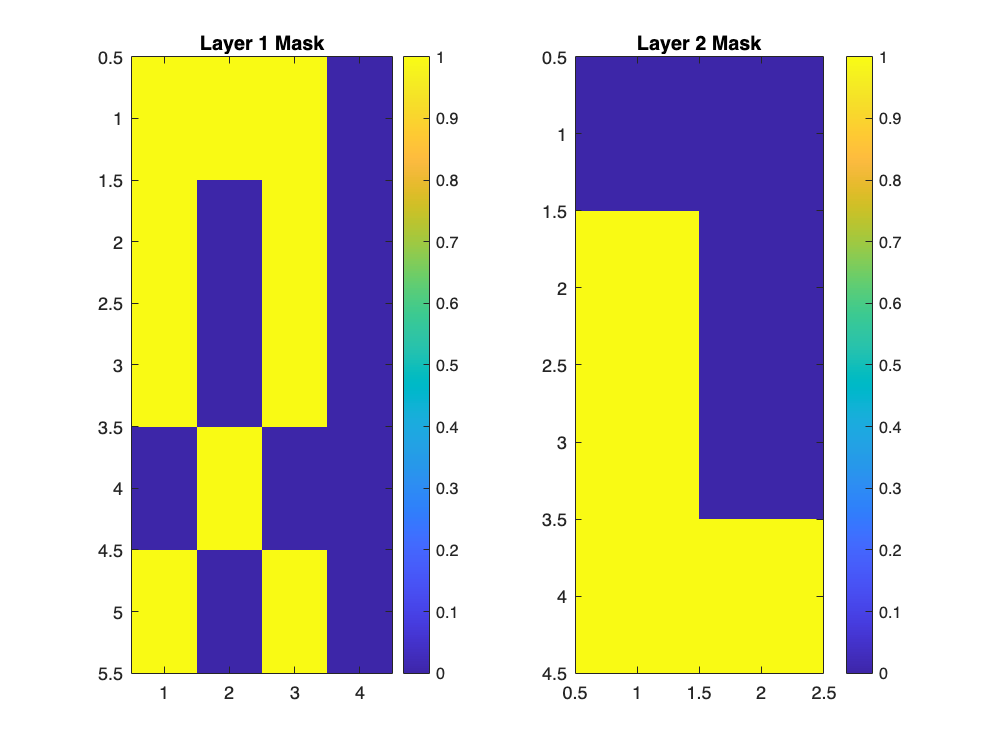

disp('Pruned Layer 2 Weights:'); disp(W2_pruned);

%% Visualize masks
figure;
subplot(1,2,1); imagesc(M1); title('Layer 1 Mask'); colorbar;

subplot(1,2,2); imagesc(M2); title('Layer 2 Mask'); colorbar;


sparsity_W1 = nnz(W1_pruned==0) / numel(W1_pruned);
sparsity_W2 = nnz(W2_pruned==0) / numel(W2_pruned);

Layer 1 sparsity: 50.00%


fprintf('Layer 1 sparsity: %.2f%%\n', sparsity_W1*100);

Layer 2 sparsity: 50.00%


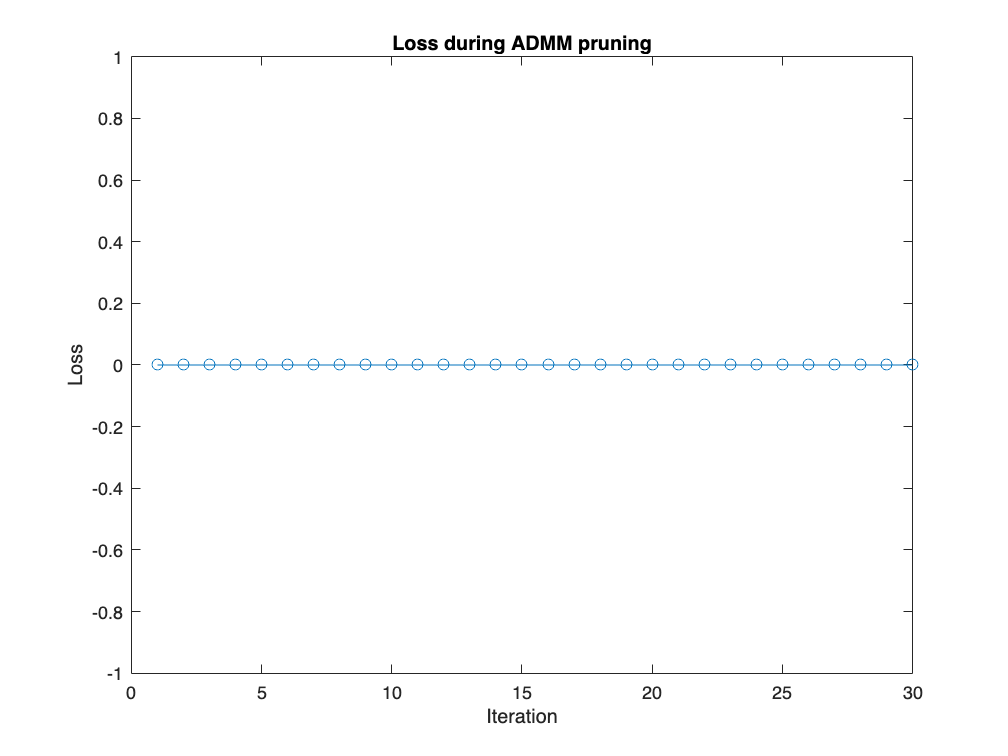

fprintf('Layer 2 sparsity: %.2f%%\n', sparsity_W2*100);

figure;
plot(loss_log, '-o'); xlabel('Iteration'); ylabel('Loss');

title('Loss during ADMM pruning');

